clc;
clear;

const_x=2;   %desplazamiento en metros de trackable1
const_y=0;
const_z=0;


folder = uigetdir();
fileList = dir(fullfile(folder, '*.csv'));
fileList = {fileList.name};
fileList

fileList = 1×3 cell array
    {'_slash_pozyx_coords.csv'}    {'_slash_vrpn_client_node_slash_explorer_coords_slash_pose.csv'}    {'_slash_vrpn_client_node_slash_referencia_slash_pose.csv'}



pozyx_data = readtable(string(fileList(1)));
trackable1_data = readtable(string(fileList(3)));
trackable2_data = readtable(string(fileList(2)));

pozyx.time=pozyx_data.rosbagTimestamp;
pozyx.position.x= pozyx_data.x/1000;
pozyx.position.y= pozyx_data.y/1000;
pozyx.position.z= pozyx_data.z/1000;


pozyx.time(pozyx.position.x==0) = [];
pozyx.position.x(pozyx.position.x==0) = [];
pozyx.position.y(pozyx.position.y==0) = [];
pozyx.position.z(pozyx.position.z==0) = [];


trackable1.time=trackable1_data.rosbagTimestamp;
trackable1.position.x= mean(trackable1_data.x);
trackable1.position.y= mean(trackable1_data.y);
trackable1.position.z= mean(trackable1_data.z);
trackable1.orientation.x= mean(trackable1_data.x_1);
trackable1.orientation.y= mean(trackable1_data.y_1);
trackable1.orientation.z= mean(trackable1_data.z_1);
trackable1.orientation.w= mean(trackable1_data.w);

trackable2.time=trackable2_data.rosbagTimestamp;
trackable2.position.x= trackable2_data.x;
trackable2.position.y= trackable2_data.y;
trackable2.position.z= trackable2_data.z;
trackable2.orientation.x= trackable2_data.x_1;
trackable2.orientation.y= trackable2_data.y_1;
trackable2.orientation.z= trackable2_data.z_1;
trackable2.orientation.w= trackable2_data.w;

quat=[trackable1.orientation.x(end) trackable1.orientation.y(end) trackable1.orientation.z(end) trackable1.orientation.w(end)];
trackable1_euler = quat2eul(quat,'XYZ');
rx=rotx(trackable1_euler(1));
ry=roty(trackable1_euler(2));
rz=rotz(trackable1_euler(3));


r_adicional=rotx(0);
z_zeros= zeros(size(trackable2.position.z));
z_zeros_pozyx= zeros(size(pozyx.position.z)+8);
m_no_rotate=[trackable2.position.x(:)'; trackable2.position.y(:)';trackable2.position.z(:)'];

m_rotate=ry*r_adicional*m_no_rotate; 


%get data time vector
pozyx_time=pozyx.time;
pozyx_time = pozyx_time/(1e9);
pozyx_time=pozyx_time-pozyx_time(1);
pozyx_time=round(pozyx_time,1);


trackable1_time=trackable1.time;
trackable1_time=trackable1_time/(1e9);
trackable1_time=trackable1_time-trackable1_time(1);
trackable1_time=round(trackable1_time,1);

trackable2_time=trackable2.time;
trackable2_time=trackable2_time/(1e9);
trackable2_time=trackable2_time-trackable2_time(1);
trackable2_time=round(trackable2_time,1);

pozyx_time

pozyx_time =          0
         0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000
    1.2000
    1.4000
    1.6000


trackable1_time

trackable1_time =          0
         0
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000


trackable2_time

trackable2_time =          0
         0
         0
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000



%% Ajuste de referencia relativa al trackable 1 y construccion de vector con tiempo
array_size=size(m_rotate);
for j=1:array_size(2)
    m_final(1,j)=m_rotate(1,j)-trackable1.position.x(end)+const_x;
    m_final(2,j)=m_rotate(2,j)-trackable1.position.y(end)+const_y;
    m_final(3,j)=m_rotate(3,j)-trackable1.position.z(end)+const_z;
    m_final(4,j)=trackable2_time(j);
end

m_final=m_final';
j=1;

for i=0:0.1:(pozyx_time(end)-0.1)
    pozyx_index_time=find(pozyx_time==i);
    trackable2_index_time=find(trackable2_time==i);
    
    if (size(pozyx_index_time,1)~=0 && size(trackable2_index_time,1)~=0)
        pozyx_index=pozyx_index_time(end);
        trackable2_index=trackable2_index_time(end);
        
        pozyx_compare(j,1)=pozyx.position.x(pozyx_index);
        pozyx_compare(j,2)=pozyx.position.y(pozyx_index);
        pozyx_compare(j,3)=pozyx.position.z(pozyx_index);
        pozyx_compare(j,4)=pozyx_time(pozyx_index);
        
        trackable2_compare(j,1)=m_final(trackable2_index,1);
        trackable2_compare(j,2)=m_final(trackable2_index,2);
        trackable2_compare(j,3)=m_final(trackable2_index,3);
        trackable2_compare(j,4)=trackable2_time(trackable2_index);
        
        j=j+1;
    end
    
end

%Seleccion de la trama de datos
for i=1:size(trackable2_compare,1)
    for j=1:4
        optitrack_final(i,j)=trackable2_compare(i,j);
        pozyx_final(i,j)=pozyx_compare(i,j);
    end
end


optitrack_final =     2.2866    0.2659    0.1393         0
    2.2865    0.2660    0.1393    0.2000
    2.2866    0.2660    0.1392    0.4000
    2.2864    0.2661    0.1391    0.8000
    2.2865    0.2659    0.1392    1.0000
    2.2865    0.2659    0.1392    1.6000
    2.2866    0.2660    0.1392    1.8000
    2.2866    0.2659    0.1393    2.0000
    2.2894    0.2645    0.1389    2.2000
    2.2866    0.2659    0.1393    2.7000


pozyx_final =     2.3690    0.2560    0.2610         0
    2.3240    0.3140    0.2920    0.2000
    2.3180    0.2240    0.2370    0.4000
    2.2970    0.2840    0.2040    0.8000
    2.3470    0.2880    0.1210    1.0000
    2.4350    0.3560    0.0530    1.6000
    2.3630    0.2960    0.2490    1.8000
    2.3630    0.3290    0.1280    2.0000
    2.3630    0.3290    0.1280    2.2000
    2.3110    0.2150    0.2880    2.7000


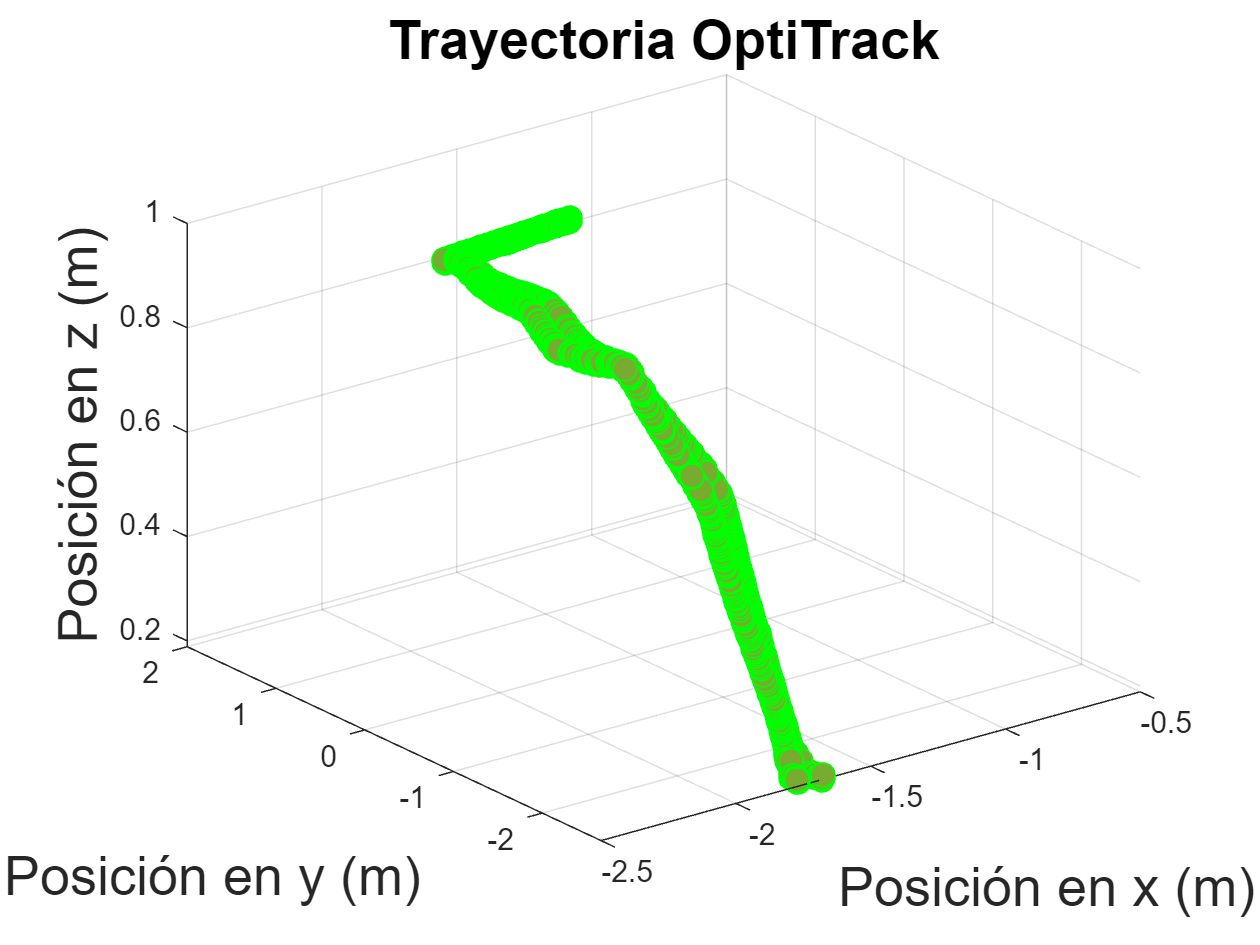


%Error de los sistemas en X e Y
error_pozyx=optitrack_final(:,1:3)-pozyx_final(:,1:3);
error_pozyx(:,4) = pozyx_final(:,4);

%Distancias euclideas entre puntos

for i=1:size(error_pozyx,1)
    p1=[pozyx_final(i,1) pozyx_final(i,2) pozyx_final(i,3)];
    p2=[optitrack_final(i,1) optitrack_final(i,2) optitrack_final(i,3)];
    norm_pozyx(i)=norm(p1-p2);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Gráfico 3D prueba
%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
plot3(trackable2.position.x, trackable2.position.y, trackable2.position.z,'o','color',[0 1 0],'MarkerFaceColor',[0.4660 0.6740 0.1880],'MarkerSize',8);
xlim([-2.5 -0.5]);
hold on;

title('Trayectoria OptiTrack', 'FontSize', 18);
xlabel('Posición en x (m)', 'FontSize', 18); 
ylabel('Posición en y (m)', 'FontSize', 18);
zlabel('Posición en z (m)', 'FontSize', 18);
grid on;


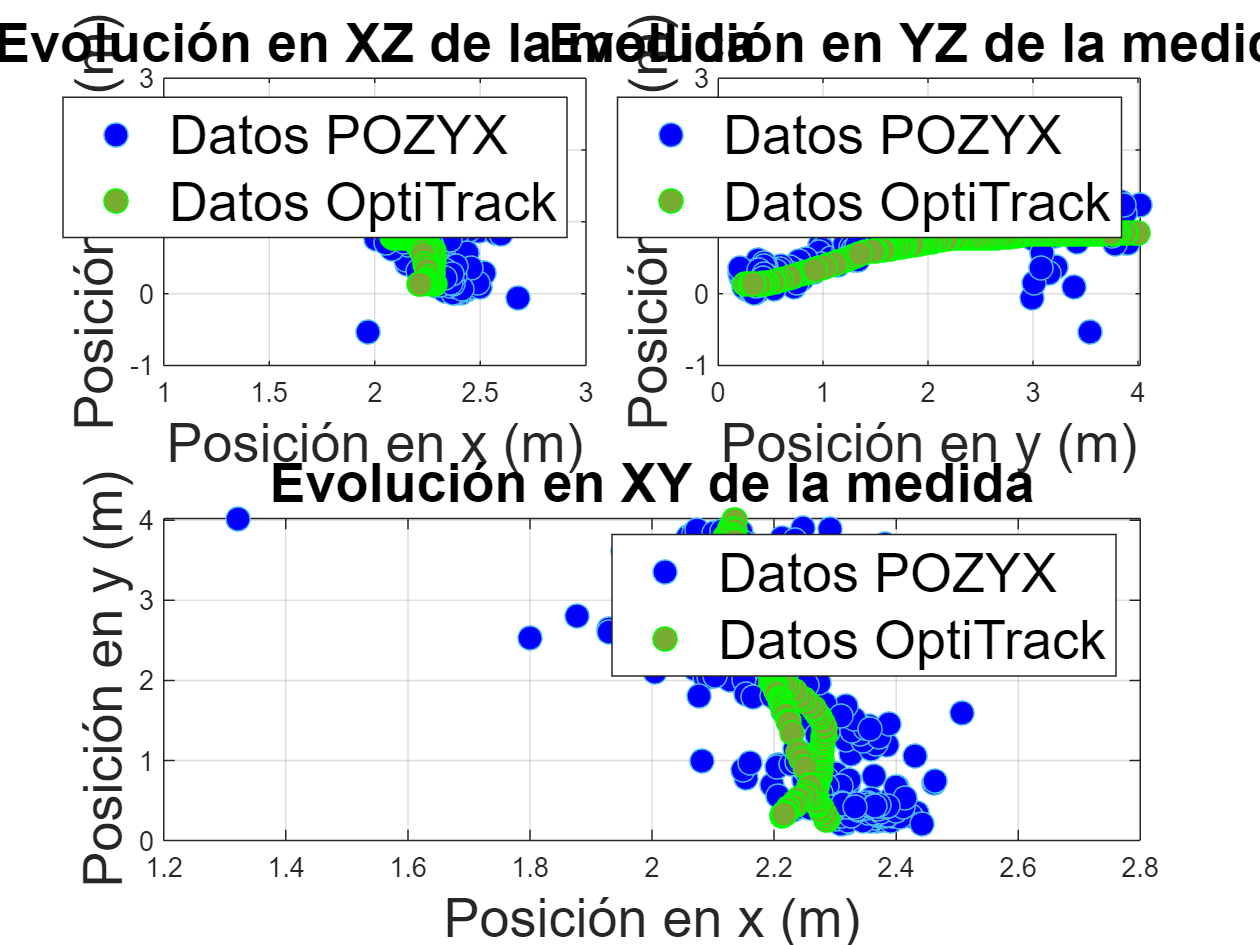


%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Gráfico de la medida Pozyx
%%%%%%%%%%%%%%%%%%%%%%%%%%

num_puntos = length(pozyx_final);
colores = jet(num_puntos);

figure
subplot(2,2,1);
plot(pozyx_final(:,1),pozyx_final(:,3),'o','color',[0.3010 0.7450 0.9330],'MarkerFaceColor',[0 0 1],'MarkerSize',8);
hold on;
plot(optitrack_final(:,1),optitrack_final(:,3),'o','color',[0 1 0],'MarkerFaceColor',[0.4660 0.6740 0.1880],'MarkerSize',8);
grid on;
title('Evolución en XZ de la medida', 'FontSize', 18);
xlabel('Posición en x (m)', 'FontSize', 18); 
ylabel('Posición en z (m)', 'FontSize', 18);
legend('Datos POZYX', 'Datos OptiTrack', 'FontSize', 18);

subplot(2,2,2);
plot(pozyx_final(:,2),pozyx_final(:,3),'o','color',[0.3010 0.7450 0.9330],'MarkerFaceColor',[0 0 1],'MarkerSize',8);
hold on;
plot(optitrack_final(:,2),optitrack_final(:,3),'o','color',[0 1 0],'MarkerFaceColor',[0.4660 0.6740 0.1880],'MarkerSize',8);
grid on;
title('Evolución en YZ de la medida', 'FontSize', 18);
xlabel('Posición en y (m)', 'FontSize', 18); 
ylabel('Posición en z (m)', 'FontSize', 18);
legend('Datos POZYX', 'Datos OptiTrack', 'FontSize', 18);

subplot(2,2,[3,4]);
plot(pozyx_final(:,1),pozyx_final(:,2),'o','color',[0.3010 0.7450 0.9330],'MarkerFaceColor',[0 0 1],'MarkerSize',8);
hold on;
plot(optitrack_final(:,1),optitrack_final(:,2),'o','color',[0 1 0],'MarkerFaceColor',[0.4660 0.6740 0.1880],'MarkerSize',8);
grid on;
title('Evolución en XY de la medida', 'FontSize', 18);
xlabel('Posición en x (m)', 'FontSize', 18); 
ylabel('Posición en y (m)', 'FontSize', 18);
legend('Datos POZYX', 'Datos OptiTrack', 'FontSize', 18);

mean(abs(error_pozyx(:,1)))

ans = 0.1029

mean(abs(error_pozyx(:,2)))

ans = 0.0865

mean(abs(error_pozyx(:,3)))

ans = 0.2754

mean(norm_pozyx)

ans = 0.3382

sqrt(mean(norm_pozyx(:).^2))

ans = 0.4219

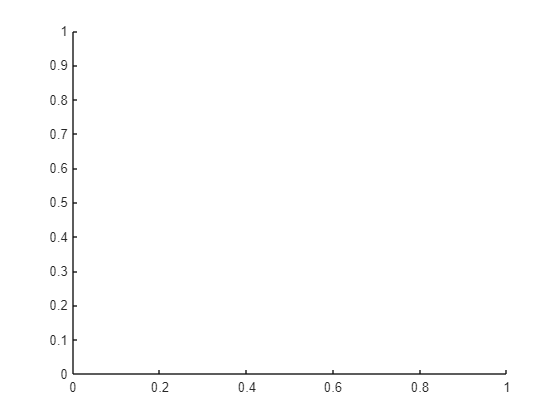

figure
hold on;

plot(pozyx_final(:,4), error_pozyx(:,1), '-o', 'color', [0.3010 0.7450 0.9330], 'MarkerFaceColor',[0 0 1],'MarkerSize',10);

Unrecognized function or variable 'pozyx_final'.

plot(pozyx_final(:,4), error_pozyx(:,2), '-o', 'color',[0 1 0], 'MarkerFaceColor',[40/255 114/255 51/255],'MarkerSize',10);
plot(pozyx_final(:,4), error_pozyx(:,3), '-o', 'color',[160/255 99/255 156/255], 'MarkerFaceColor',[76/255 40/255 130/255],'MarkerSize',10);
plot(pozyx_final(:,4),norm_pozyx, '-o', 'color', [1 0 0], 'MarkerFaceColor',[203/255 50/255 52/255],'MarkerSize',10);
grid on;
title('Evolución de los errores: ', 'FontSize', 18);
xlabel('Tiempo en segundos', 'FontSize', 18);
ylabel('Error (m)', 'FontSize', 18);
legend('Error en el eje x', 'Error en el eje y', 'Error en el eje z', 'Norma del error', 'FontSize', 18);
hold off;

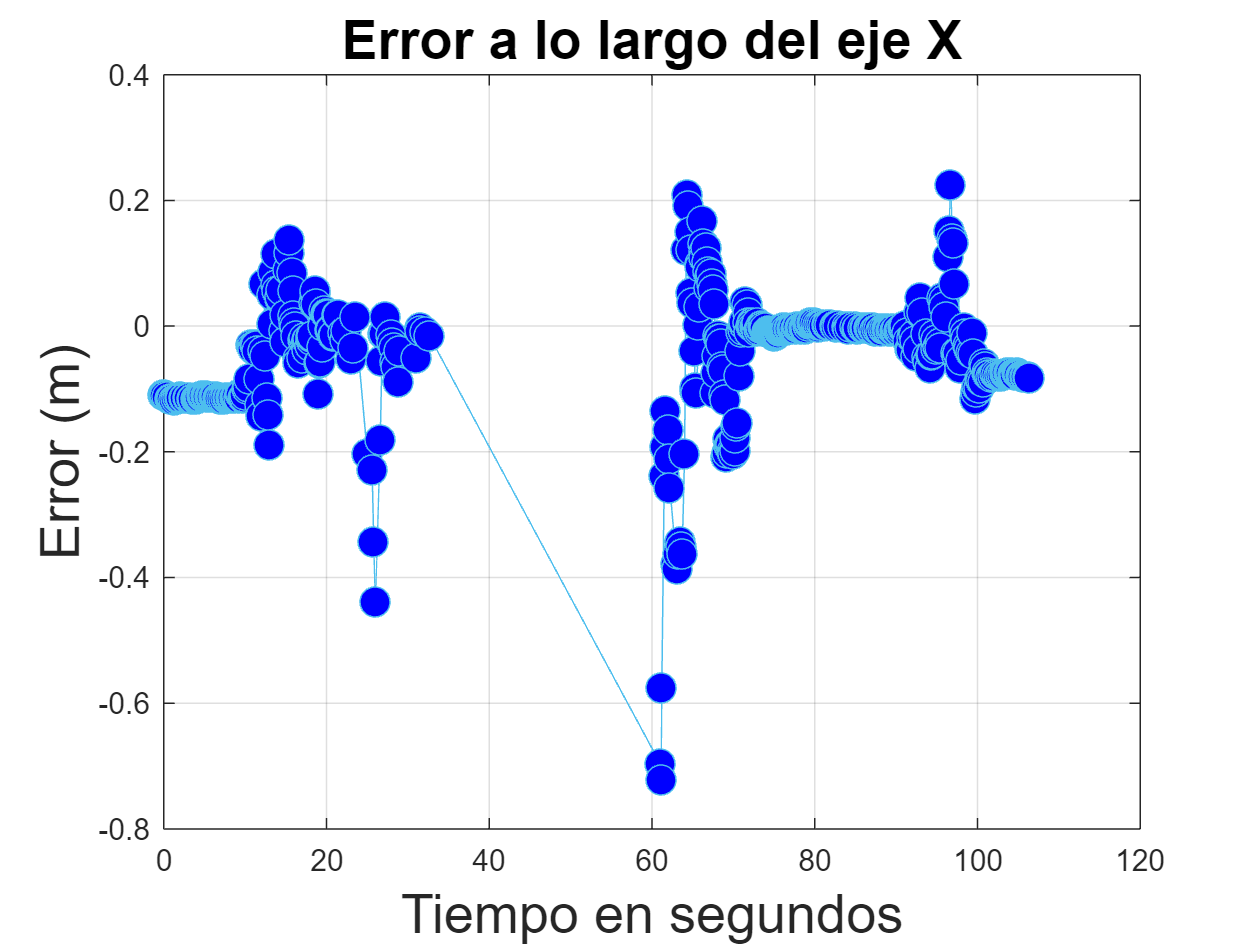

%%%%%%%%%%%%%%%%%%%%%%%  
%Gráfico del error en X
%%%%%%%%%%%%%%%%%%%%%%%
figure
plot(error_pozyx(:,4), error_pozyx(:,1), '-o', 'color', [0.3010 0.7450 0.9330], 'MarkerFaceColor',[0 0 1], 'MarkerSize', 10);
grid on;
title('Error a lo largo del eje X', 'FontSize', 18);
xlabel('Tiempo en segundos', 'FontSize', 18);
ylabel('Error (m)', 'FontSize', 18);

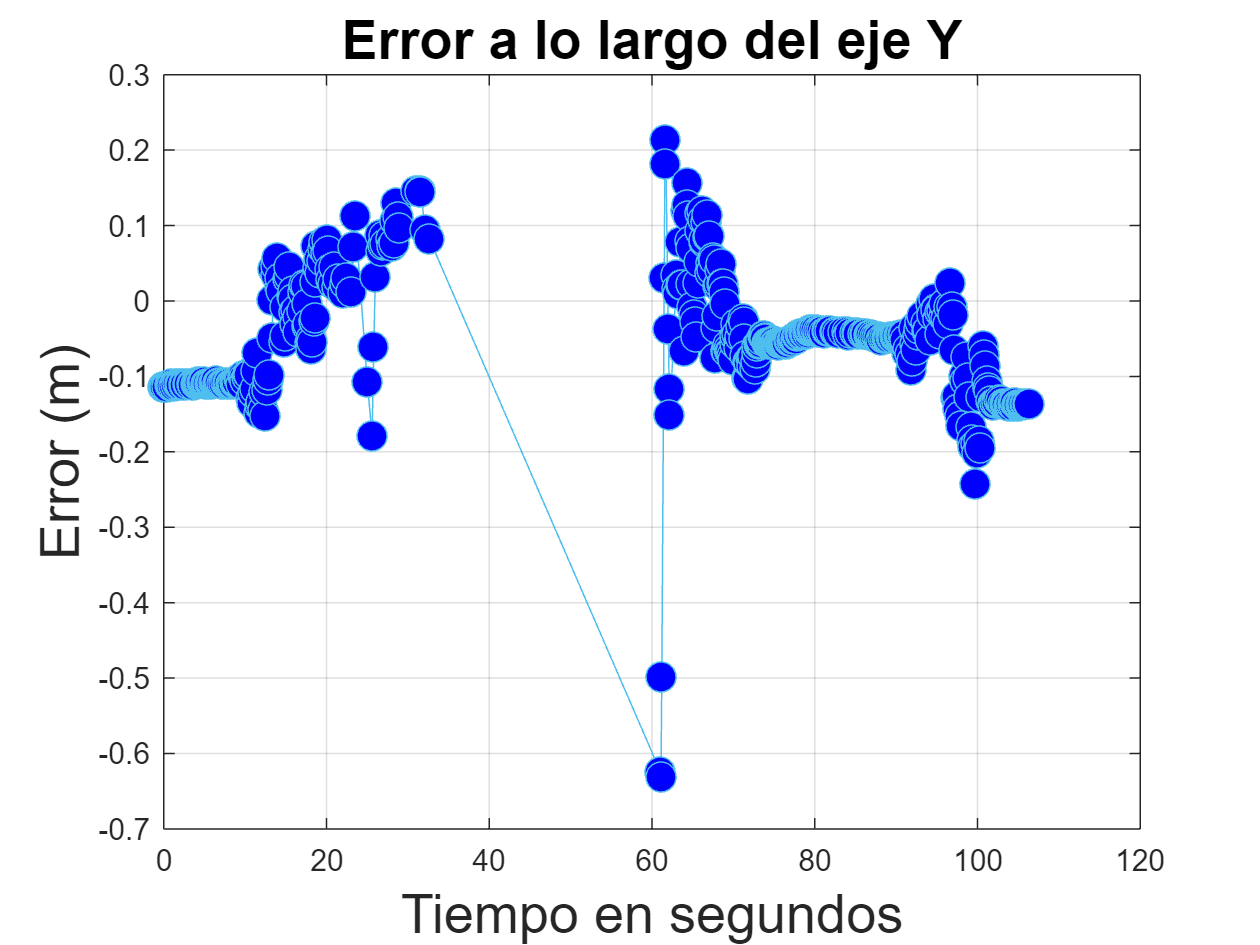


%%%%%%%%%%%%%%%%%%%%%%%
%Gráfico del error en Y
%%%%%%%%%%%%%%%%%%%%%%%
plot(error_pozyx(:,4), error_pozyx(:,2), '-o', 'color', [0.3010 0.7450 0.9330], 'MarkerFaceColor',[0 0 1], 'MarkerSize', 10);
grid on;
title('Error a lo largo del eje Y', 'FontSize', 18);
xlabel('Tiempo en segundos', 'FontSize', 18);
ylabel('Error (m)', 'FontSize', 18);

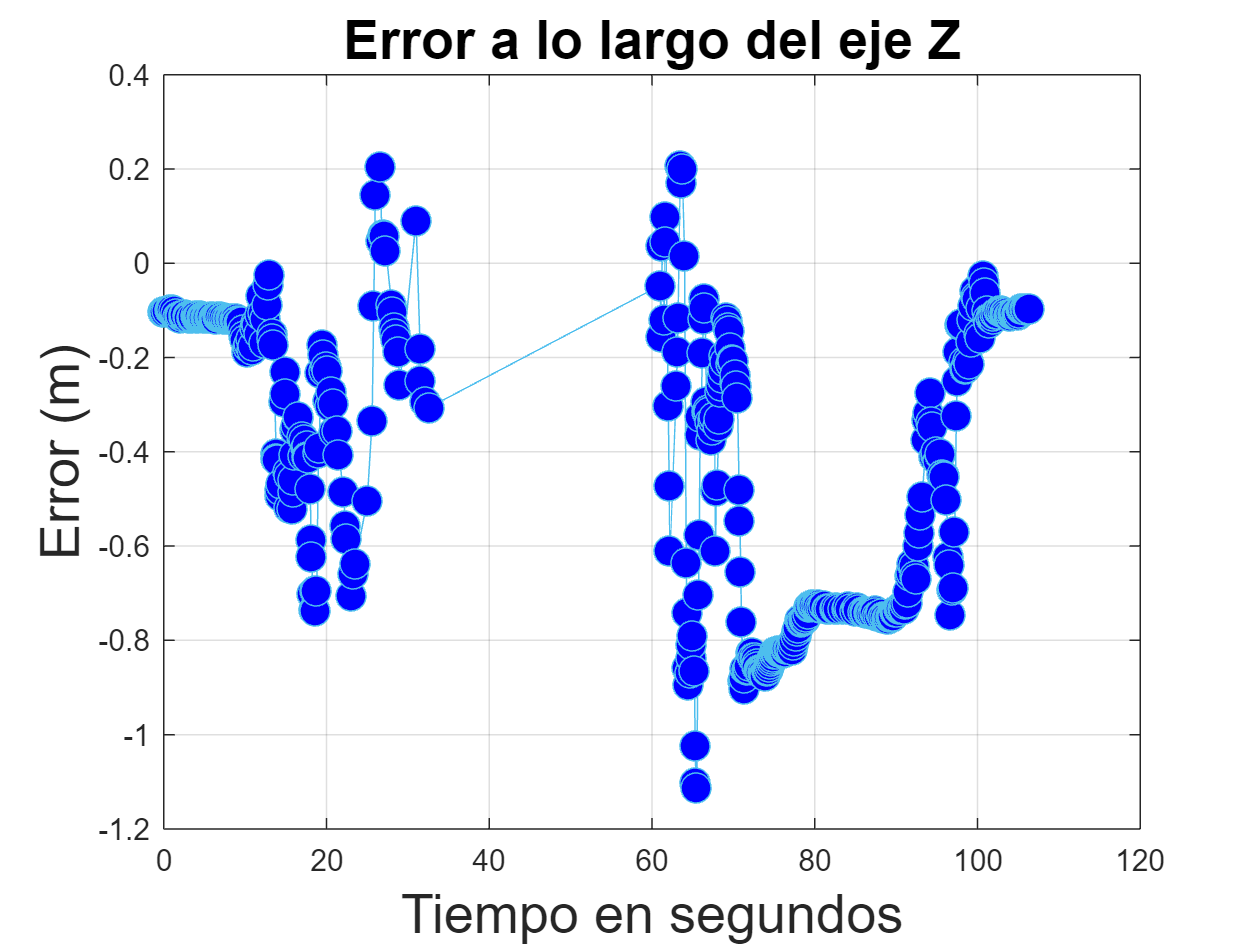


%%%%%%%%%%%%%%%%%%%%%%%
%Gráfico del error en Z
%%%%%%%%%%%%%%%%%%%%%%%
plot(error_pozyx(:,4), error_pozyx(:,3), '-o', 'color', [0.3010 0.7450 0.9330], 'MarkerFaceColor',[0 0 1], 'MarkerSize', 10);
grid on;
title('Error a lo largo del eje Z', 'FontSize', 18);
xlabel('Tiempo en segundos', 'FontSize', 18);
ylabel('Error (m)', 'FontSize', 18);

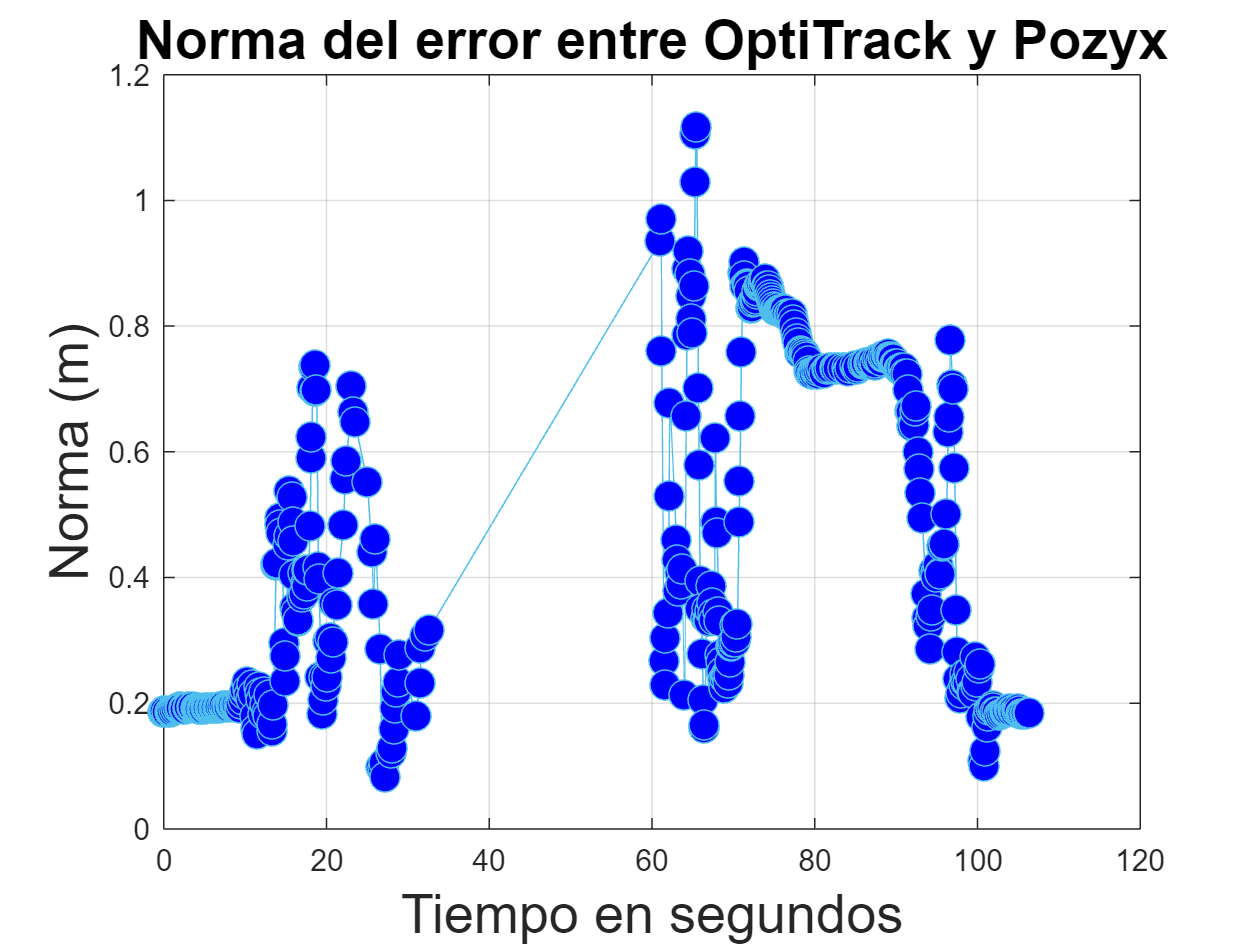


%%%%%%%%%%%%%%%%%%%%
%Gráfico de la norma
%%%%%%%%%%%%%%%%%%%%
plot(error_pozyx(:,4), norm_pozyx, '-o', 'color', [0.3010 0.7450 0.9330], 'MarkerFaceColor',[0 0 1], 'MarkerSize', 10);
hold on;
grid on;
title('Norma del error entre OptiTrack y Pozyx', 'FontSize', 18);
xlabel('Tiempo en segundos', 'FontSize', 18);
ylabel('Norma (m)', 'FontSize', 18);

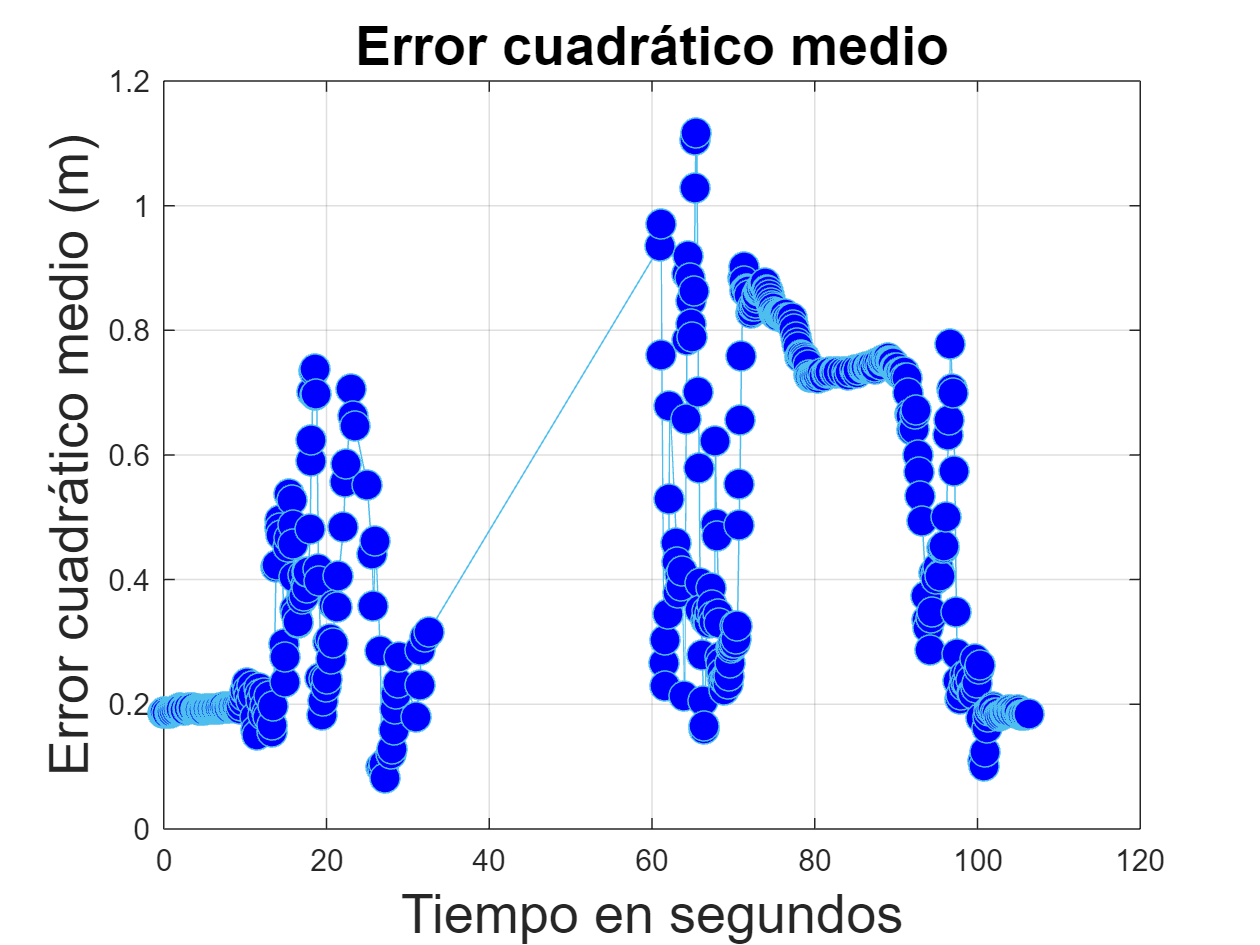


%%%%%%%%%%%%%%%%%%%%
%Gráfico del RMSE
%%%%%%%%%%%%%%%%%%%%
figure
plot(error_pozyx(:,4), RMSE, '-o', 'color',[0.3010 0.7450 0.9330], 'MarkerFaceColor',[0 0 1], 'MarkerSize', 10);
hold on
grid on;
title('Error cuadrático medio','FontSize',18);
xlabel('Tiempo en segundos','FontSize',18);
ylabel('Error cuadrático medio (m)','FontSize',18);